# Create and Customize Stacked Plots

`stackedplot` creates stacked plots of several variables with a common x-axis.

### Read Patients Data

We will use "`patients.mat" `to demonstrate how to create and customize stacked plots. The MAT-file contains various medical patient data of 100 patients. Use a helper function to sort the data in order of patient weight and place the relevant variables in a table.

tbl = readPatientData();

### Basic Stacked Plot

To understand if the blood pressures changes with an increase in patient weight, view the systolic and diastolic blood pressures of patients along with their weights. From the data, there is no clear trend in the blood pressure with increasing weight.

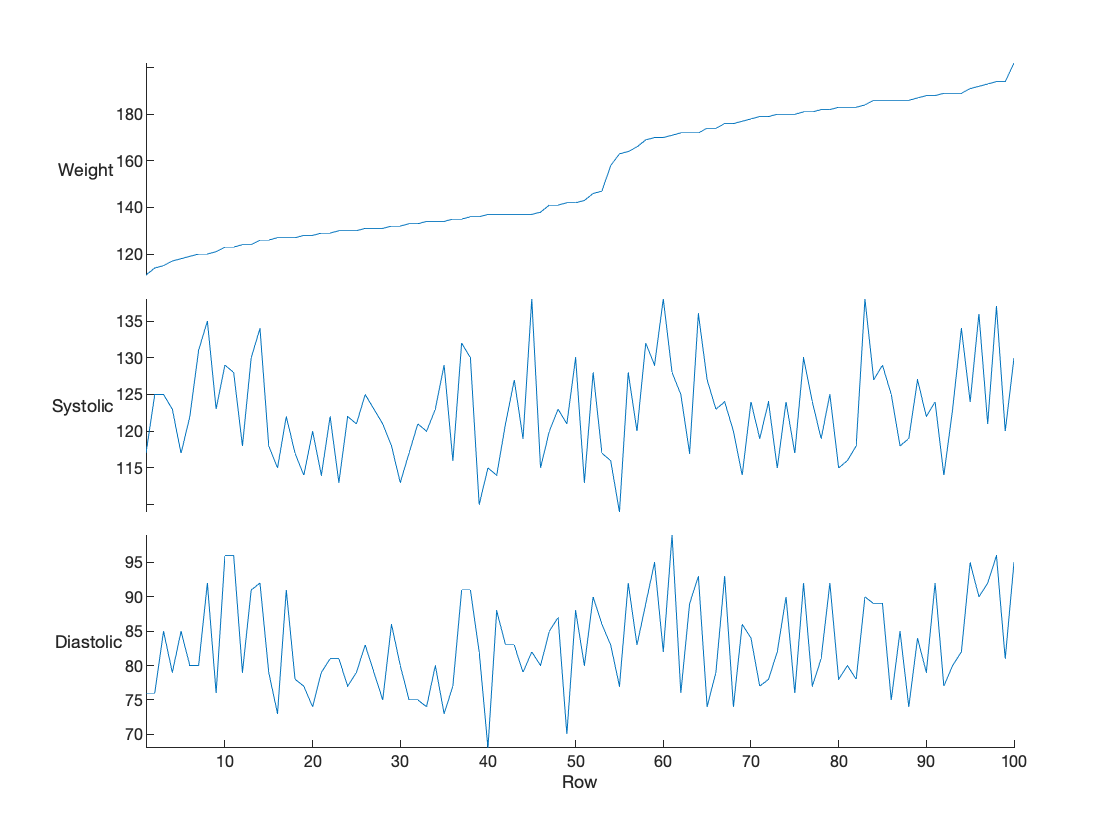

stackedplot(tbl);

## Customization

### Specify Variable Order

Use the second input to `stackedplot` to customize the variable order on the plot. Combine systolic and diastolic pressures on the same y-axis since they have the same units

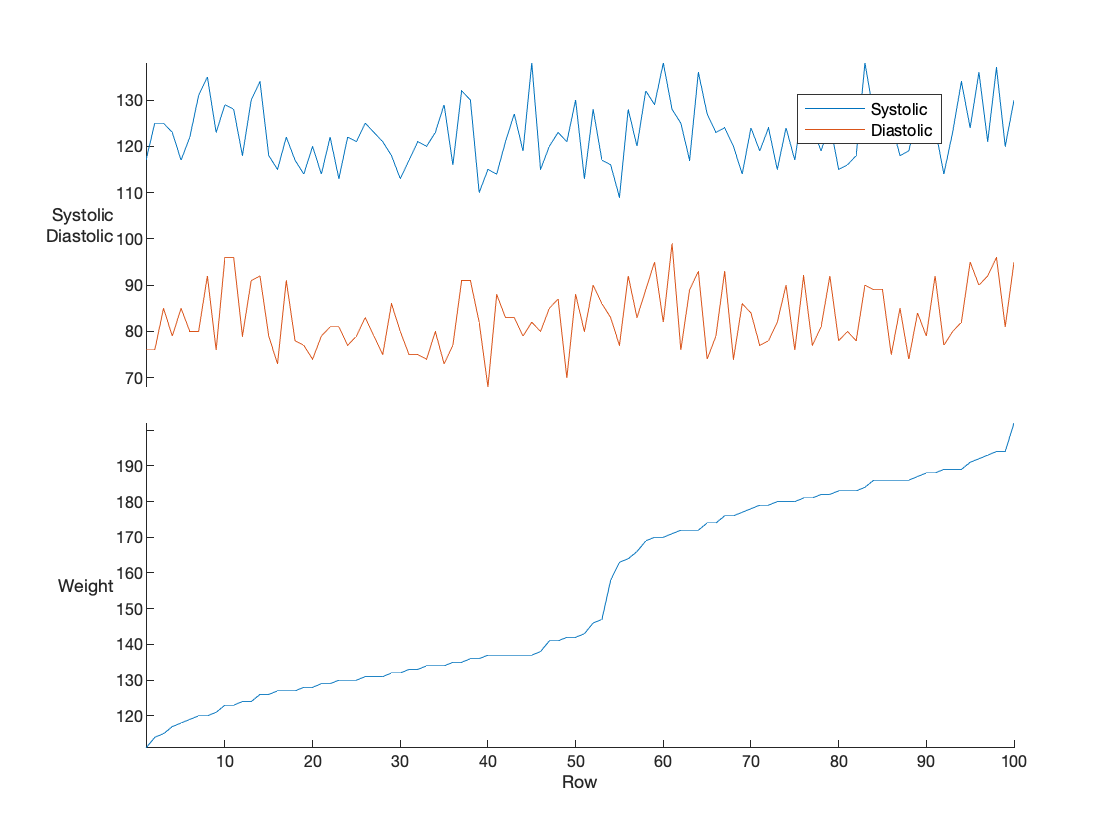

vars = {{"Systolic","Diastolic"},"Weight"};
s = stackedplot(tbl,vars);

### Change Individual Line Properties

Access the plot handle to change individual line properties. For example, make the Weight plot have a black line and specify different Marker styles for the Systolic and Diastolic plots. The line width for all lines can be specified using the *LineWidth* property as a Name, Value pair argument to `stackedplot.`

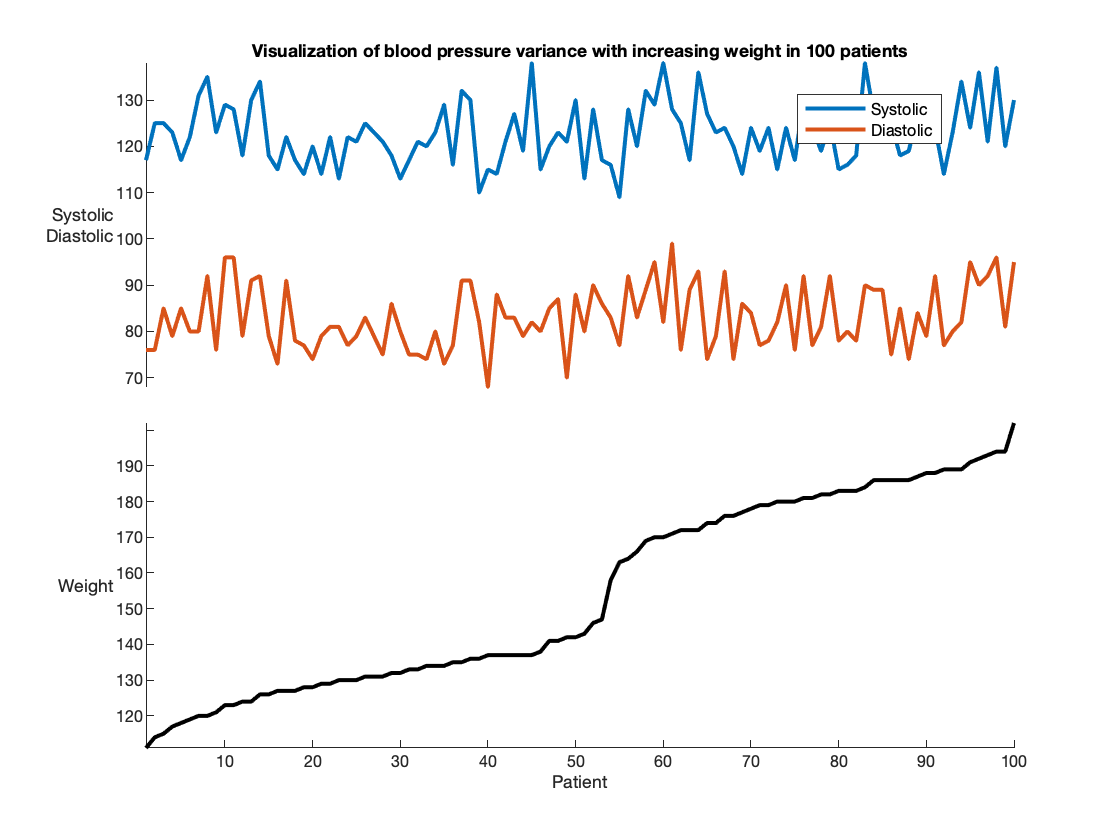

LineWidth = 2;
LineColor = 'k';
sysMarker = 'none';
diasMarker = 'none';

figure
s1 = stackedplot(tbl,vars,...
    "LineWidth",LineWidth);                           % Specify line width for all plots        
s1.LineProperties(2).Color = LineColor;               % Specify weight plot color
s1.LineProperties(1).Marker = {sysMarker,diasMarker}; % Specify individual plot customization
xlabel("Patient");
title("Visualization of blood pressure variance with increasing weight in 100 patients")

### Change Axes Properties

Access the plot handle to change axes properties. For example, specify the location of the legend as East to minimize interference with plots and adjust the *YLimits* of the top axis to reduce interference with the title.

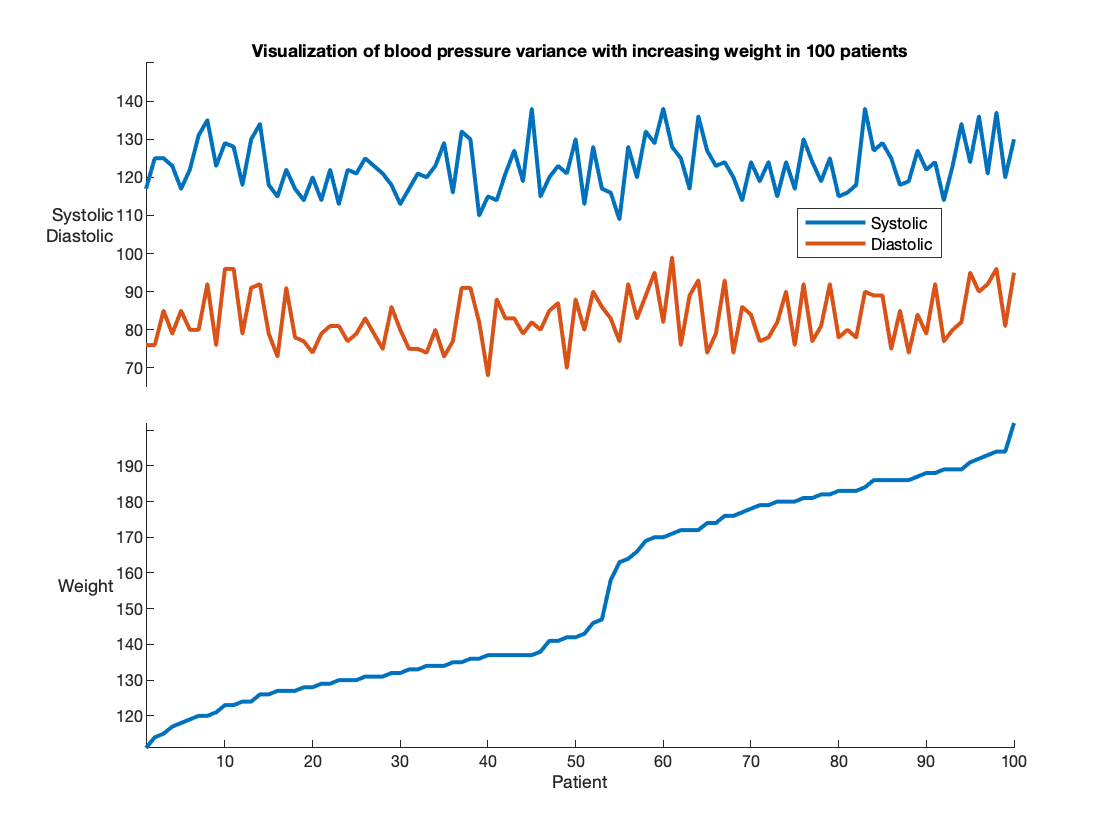

s2 = stackedplot(tbl,vars,"LineWidth",2);
s2.AxesProperties(1).LegendLocation = 'east';
s2.AxesProperties(1).YLimits = [65, 150];
xlabel("Patient");
title("Visualization of blood pressure variance with increasing weight in 100 patients")

## **Additional Information**

### **Get All StackedLine Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a StackedLine, uncomment the following code. View or modify these properties using dot notation.

% get(s)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[stackedplot](https://www.mathworks.com/help/matlab/ref/stackedplot.html)

### Helper Functions

This helper function reads in patient data, sorts it by increasing weight and places three variables (Weight, Systolic, Diastolic) into a table.

function [tbl] = readPatientData()
    load("patients.mat");
    [Weight, idx] = sort(Weight);
    Systolic = Systolic(idx);
    Diastolic = Diastolic(idx);
    tbl = table(Weight, Systolic, Diastolic);
end

Copyright (c) 2021, The MathWorks, Inc.